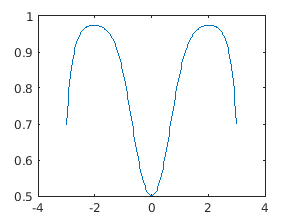

x= linspace(-3,3,200);
y = 1./(1+exp(-2*sin(x).*x));
plot(x,y)

% constructing least square matrix
M=x'.^(0:9)

M = 	1.0e+04 *

    0.0001   -0.0003    0.0009   -0.0027    0.0081   -0.0243    0.0729   -0.2187    0.6561   -1.9683
    0.0001   -0.0003    0.0009   -0.0026    0.0078   -0.0231    0.0686   -0.2038    0.6052   -1.7973
    0.0001   -0.0003    0.0009   -0.0025    0.0075   -0.0220    0.0645   -0.1897    0.5577   -1.6396
    0.0001   -0.0003    0.0008   -0.0025    0.0072   -0.0209    0.0607   -0.1765    0.5136   -1.4943
    0.0001   -0.0003    0.0008   -0.0024    0.0069   -0.0198    0.0570   -0.1641    0.4725   -1.3605
    0.0001   -0.0003    0.0008   -0.0023    0.0066   -0.0188    0.0535   -0.1524    0.4344   -1.2376
    0.0001   -0.0003    0.0008   -0.0022    0.0063   -0.0178    0.0502   -0.1415    0.3989   -1.1246
    0.0001   -0.0003    0.0008   -0.0022    0.0061   -0.0169    0.0471   -0.1312    0.3660   -1.0208
    0.0001   -0.0003    0.0008   -0.0021    0.0058   -0.0160    0.0441   -0.1216    0.3355   -0.9257
    0.0001   -0.0003    0.0007   -0.0020    0.0055   -0.0151    0.0413   -0

A=inv(M'*M)*M'*y'

A =     0.5141
   -0.0000
    0.4422
    0.0000
   -0.1487
   -0.0000
    0.0210
    0.0000
   -0.0011
   -0.0000


Ax=M*A

Ax =     0.6740
    0.7210
    0.7613
    0.7956
    0.8248
    0.8493
    0.8699
    0.8869
    0.9009
    0.9123


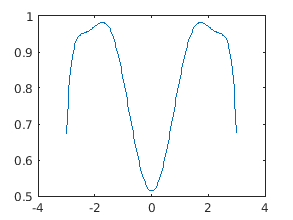

plot(x,Ax)